## 0 Data Preparation

% change path
path = matlab.desktop.editor.getActiveFilename;
path = erase(path,'2nd_Exp - Result.mlx'); % if you change the filename, modify this line
cd(path)

% load data
resultTable = readtable('test_results - cleaned and structured.csv');

## 1 Independent Variables

% convert nominal columns into categorical data type

% Participant_Information
resultTable.Gender = categorical(resultTable.Gender);
resultTable.AgeGroup = categorical(resultTable.AgeGroup);
resultTable.HourSpent = categorical(resultTable.HourSpent);
resultTable.Hand = categorical(resultTable.Hand);

% Stimulus_Information
resultTable.StemMood = categorical(resultTable.StemMood);

% Condition_Information
%resultTable.Condition = categorical(resultTable.Condition);
resultTable.CondNum = categorical(resultTable.CondNum);

## 2 Dependent Variables - PressedKey

% PressedKey, F (yes) = 1, J (no) = 0

### 2.1 PressedKey - Descriptive Statistics

% Descriptive Statistics

% Data Summary of categorical data: Mode

keyMode = groupsummary(resultTable, 'Condition','mode', 'PressedKey')

keyMode = 5×3 table
           Condition            GroupCount    mode_PressedKey
    ________________________    __________    _______________

    {'control'             }       233               1       
    {'emoji ambiguous'     }       229               1       
    {'emoji irony'         }       232               0       
    {'linguistic ambiguous'}       234               1       
    {'linguistic irony'    }       236               0       


The `groupsummary` function draws data from the csv table `resultTable`, and then find `mode` values of `PressedKey` grouped by `Condition`.

Data Summary: Mode - Descritpion

control: mode = 1  

- e.g the stimulus "สวย" was displayed, most participants pressed 'F', implying they thought the stimulus item conveys its literal meaning ("สวย").

emoji ambiguous: mode = 1

- e.g the stimulus "สวย (emoji ambiguous)" was displayed, most participants pressed 'F', implying they thought the stimulus item conveys its literal meaning ("สวย"). 

emoji irony: mode = 0 

- e.g the stimulus "สวย (emoji irony)" was displayed, most participants pressed 'J',  implying they thought the stimulus item conveys its opposite meaning ("ไม่สวย").

linguistic ambiguous: mode = 1

- e.g the stimulus "ส๊วยยสวย" was displayed, most participants pressed 'F', implying that they thought the stimulus item conveys its literal meaning ("สวย").

linguistic irony: mode = 0

- e.g the stimulus "สวยบ้านแกสิ" was displayed, most participants pressed 'J',  implying they thought the stimulus item conveys its opposite meaning ("ไม่สวย").

#### Bar Chart - Percantage Counts of Key 'J' [0] Pressed on Each condition

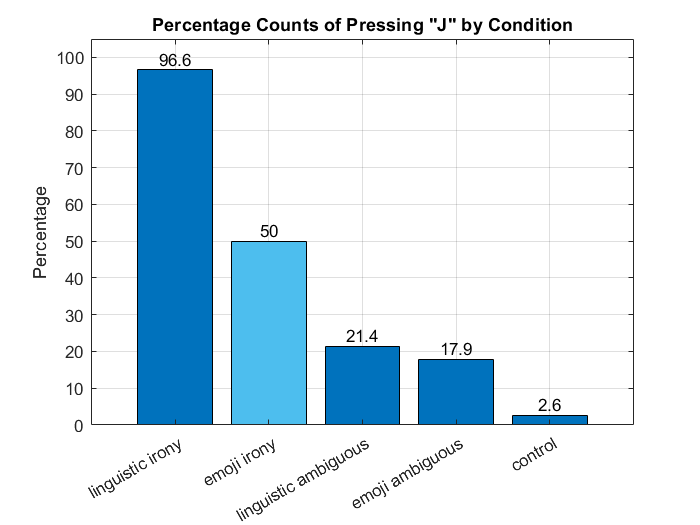

% Plot a bar chart of count of key 'J' pressed (0, the stimulus conveys its opposite meaning)

% Extract the unique condtions 
uniqCond = unique(resultTable.Condition);

% Create empty arrays for storing how many times each key is opted on each condition 
Press1 = nan(1, length(uniqCond));
Press0 = nan(1, length(uniqCond));

% Create empty arrays for storing, of each condition, total number of keys pressed and sum of times when key 'F' is pressed, respectively 
Total = nan(1, length(uniqCond));
SumOfF = nan(1, length(uniqCond));

% Calculate for how many times each key is opted on each condition  
for i = 1:height(uniqCond) % i means each Condition
    key = resultTable.PressedKey(strcmp(resultTable.Condition, uniqCond{i})); % logical indexing both keys pressed on each condition
    Total(i) = length(key); % storing a total number of both pressed keys per condition
    SumOfF(i) = sum(key); % summation of 1 in the variable 'total' shows counts of Key-'F' pressed
    Press1(i) = (SumOfF(i)/Total(i))*100; % store in the array 'Press1' the percentage count of Key 'F' pressed
    Press0(i) = ((Total(i) - SumOfF(i))/Total(i))*100; % store in the array 'Press0' the percentage count of Key 'J' pressed
end

%for i = 1:height(uniqCond) % i means each Condition
%    key = resultTable.PressedKey(strcmp(resultTable.Condition, uniqCond{i})); % logical indexing both keys pressed on each condition
%    total = length(key); storeTotal(i) = total; % storing a total number of both pressed keys per condition
%    P1 = sum(key); storeSumOfF(i) = P1; % summation of 1 in the variable 'total' shows counts of Key-'F' pressed
%    Press1(i) = (P1/total)*100; % store in the array 'Press1' the percentage count of Key 'F' pressed
%    Press0(i) = ((total - P1)/total)*100; % store in the array 'Press0' the percentage count of Key 'J' pressed
%end    

% Sorting the result
X = categorical(uniqCond');
X = reordercats(X,{'linguistic irony','emoji irony', 'linguistic ambiguous','emoji ambiguous', 'control'});

% Data Visualization
b = bar(X, round(Press0,1));
xtips = b.XEndPoints;
ytips = b.YEndPoints;
ylim([0 105])
labels = string(b.YData);
text(xtips,ytips,labels,'HorizontalAlignment','center','VerticalAlignment','bottom')

b.FaceColor = 'flat';
b.CData(2,:) = [0.3010 0.7450 0.9330];

title('Percentage Counts of Pressing "J" by Condition')
ylabel('Percentage')
grid on


% Note
    % more specific with each condition, percentage relative frequency

### 2.2 PressedKey - Inferential Statistics 

#### Logistic Regression

% Logistic Regression

% Note
    % random effect: ItemID, PartID
    % compare: emoji irony and linguistic irony

% baseline: negative, control, man, 16-25 
%modelspec = 'PressedKey ~ Condition + Gender + AgeGroup' ;
modelspec = ['PressedKey ~ (StemMood * Condition) + StemFreq + Gender + AgeGroup + HourSpent + Hand'] ;
mdl = fitglm(resultTable,modelspec,'Distribution','binomial')

mdl = Generalized linear regression model:
    logit(PressedKey) ~ 1 + StemFreq + Gender + AgeGroup + HourSpent + Hand + StemMood*Condition
    Distribution = Binomial

Estimated Coefficients:
                                                         Estimate          SE          tStat        pValue  
                                                        ___________    __________    _________    __________

    (Intercept)                                              4.9727       0.97544       5.0979    3.4342e-07
    StemFreq                                            -0.00020352    0.00011382      -1.7882      0.073748
    StemMood_positive                                      -0.73364        0.8834     -0.83047       0.40627
    Condition_emoji ambiguous                            

#### Mixied-Effect Logistic Regression

% mixed-effect Logistic regression

mdlN = fitglme(resultTable, ['PressedKey ~ (StemMood * Condition) + StemFreq + Gender + AgeGroup + HourSpent + Hand' ...
    '+ (1|PartID) + (1|ItemID) + (1+StemFreq|ItemID)'], 'Distribution','Binomial')

mdlN = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1164
    Fixed effects coefficients          23
    Random effects coefficients        130
    Covariance parameters                5
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    PressedKey ~ 1 + StemFreq + Gender + AgeGroup + HourSpent + Hand + StemMood*Condition + (1 | PartID) + (1 | ItemID) + (1 + StemFreq | ItemID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    6761.9    6903.6    -3353            6705.9  

Fixed effects coefficients (95% CIs):
    Name                                                        Estimate       SE            tStat       DF      pValue        Lower          Upper     
    {'(Intercept)'                                     }         

## 3 Dependent Variable - ReactionTime 

### 3.1 ReactionTime  - Descriptive Statistics

- Key "J" pressed - think that the stimulus item implies its opposite meaning

% Extract the reaction time values and their condition where Key-0 is opted  
x = resultTable.PressedKey == 0;
y = resultTable.ReactionTime(x);
x1 = resultTable.Condition(x);

% Build a new table containing the reaction time data and their condition | Key-0 is pressed
clear T
T.ReactionTime = y;
T.Condition = x1;
tbl = struct2table(T);

% Data Summary: Median
rtMedian0 = groupsummary(tbl, 'Condition','median', 'ReactionTime')

rtMedian0 = 5×3 table
           Condition            GroupCount    median_ReactionTime
    ________________________    __________    ___________________

    {'control'             }         6                1913       
    {'emoji ambiguous'     }        41                2265       
    {'emoji irony'         }       116                2129       
    {'linguistic ambiguous'}        50                2170       
    {'linguistic irony'    }       228              1736.5       


#### Box Plot - Reaction Time of Pressing "J" on Each Condition

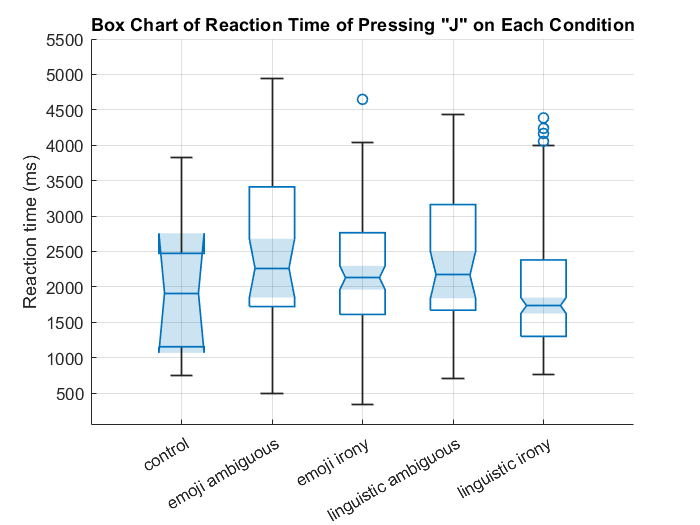

% Data Visualization

%figure;
%boxchart(categorical(x1), y, "Notch","on")
%ylabel("Reaction time (ms)")
%ylim([500 5500])
%gtitle('Box Chart of Reaction Time Answering No (Press 0) on Each Condition')
figure;
boxchart(categorical(tbl.Condition), tbl.ReactionTime, "Notch","on")
ylabel("Reaction time (ms)")
ylim([50 5500])
title('Box Chart of Reaction Time of Pressing "J" on Each Condition')
grid on

### 3.2 ReactionTime  - Inferential Statistics

#### Linear Regression

% fit linear regression

testmdl1 = 'ReactionTime ~ (Condition * StemMood) + StemFreq + Gender + AgeGroup + HourSpent + Hand';
%testmdl1 = 'ReactionTime ~ StemFreq * StemMood * Condition * Gender * AgeGroup + HourSpent';
%testmdl1 = 'ReactionTime ~ StemFreq + StemMood + Condition + Gender + AgeGroup + HourSpent';

mdl1 = fitlm(resultTable, testmdl1)

mdl1 = Linear regression model:
    ReactionTime ~ 1 + StemFreq + Gender + AgeGroup + HourSpent + Hand + StemMood*Condition

Estimated Coefficients:
                                                        Estimate       SE        tStat      pValue 
                                                        _________    _______    ________    _______

    (Intercept)                                            1932.7     1296.8      1.4904     0.1364
    StemFreq                                            -0.061273    0.21369    -0.28674    0.77436
    StemMood_positive                                     -511.79     731.97    -0.69919    0.48458
    Condition_emoji ambiguous                              625.57     736.89     0.84893     0.3961
    Condition_emoji irony             

#### Mixed-Effect Linear Regression

% mixed-effect linear regression
mdlNull = fitlme(resultTable,['ReactionTime ~ (Condition * StemMood) + StemFreq + Gender + AgeGroup + HourSpent ' ...
    '+ (1|PartID) + (1|ItemID) + (1+StemFreq|ItemID) + (1+Condition|PartID)'])

mdlNull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1164
    Fixed effects coefficients          22
    Random effects coefficients        330
    Covariance parameters               21

Formula:
    ReactionTime ~ 1 + StemFreq + Gender + AgeGroup + HourSpent + StemMood*Condition + (1 | PartID) + (1 | ItemID) + (1 + StemFreq | ItemID) + (1 + Condition | PartID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    23374    23591    -11644           23288   

Fixed effects coefficients (95% CIs):
    Name                                                        Estimate     SE         tStat         DF      pValue     Lower       Upper  
    {'(Intercept)'                                     }           2650.6     1030.7        2.5715    1142    0.01025      628.23     4672.9
    {'StemFreq'                                        }  